clf;
w = logspace(-1,2,100);
for k = 1:100
    s = 1i * w(k);
    G(k) = 20 / (0.5*s+1);
end
semilogx(w,20*log10(abs(G)),'r',w,angle(G)*180/pi,'r--');
hold on
finesemilogx([0],[0],'off','Frequency Response','\omega (rad/s)','Y(j\omega)',[-1 2],[-90 40],'off',[400 400]);

ans = 0.2005

ans = 40

dy = 1.5294

ans =     0.1002    0.1000    0.0501


ans =    38.4706   40.0000   38.4706


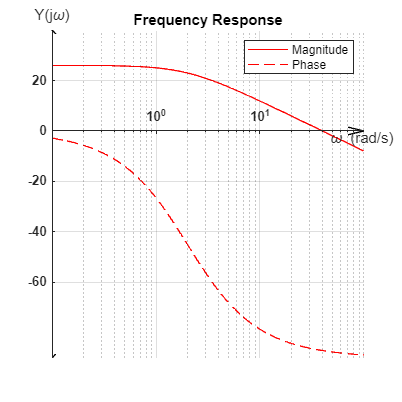

legend('Magnitude','Phase','','','','','')
grid on

clf;
w = logspace(-1,2,100);
for k = 1:100
    s = 1i * w(k);
    G(k) = 20 / (0.5*s+1);
end
semilogx(w,20*log10(abs(G)),'r',w,angle(G)*180/pi,'r--');
hold on
w = logspace(-1,2,10);
sys = tf([20],[0.5 1]);
amp = w.*0;
phase = w.*0;
for i = 1:length(w)
    t = linspace(0,100,100001);
    r = cos(w(i)*t);
    x = lsim(sys,r,t);
    R = fft(r);
    [Kr,indexr] = max(abs(fft(r)));
    tempphase = angle(R(indexr));
    X = fft(x);
    [K,index] = max(abs(X));
    [Kr,indexr] = max(abs(R));
    amp(i) = K/Kr;
    phase(i) = angle(X(index)) - tempphase;
end
semilogx(w,20*log10(amp),'bx',w,phase*180/pi,'bo','LineWidth',1.3);
finesemilogx([0],[0],'off','Frequency Response','\omega (rad/s)','Y(j\omega)',[-1 2],[-90 40],'off',[400 400]);

ans = 0.2005

ans = 40

dy = 1.5294

ans =     0.1002    0.1000    0.0501


ans =    38.4706   40.0000   38.4706


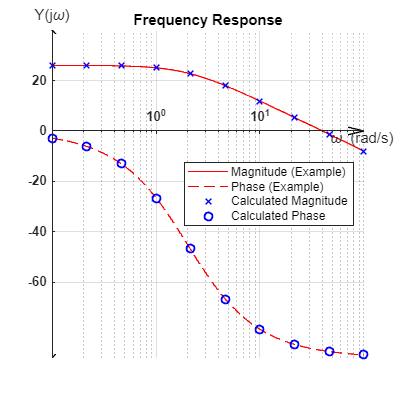

legend('Magnitude (Example)','Phase (Example)','Calculated Magnitude','Calculated Phase','','','','','','Location','east')
grid on

% 
%     w = logspace(-1,2,10);
%     sys = tf([20],[0.5 1]);
%     amp = zeros([1,length(w)]); 
%     phase = amp; %create a clone empty array
%     for i = 1:length(w)
%         t = linspace(0,100,100001);
%         r = cos(w(i)*t);
%         r_phase = angle(R(find(max(abs(fft(r)))==r)))
%         X = fft(lsim(sys,r,t));
%         [K,index] = max(abs(X));
%         amp(i) = K;
%         phase(i)=angle(X(index))-r_phase;
%     end
%     semilogx(w,20*log10(amp));
%     hold on
%     semilogx(w,phase*180/pi,'--')
%     grid on

% clf;
% w = logspace(-1,2,10);
% hold on
% sys = tf([20],[0.5 1]);
% amp = w.*0;
% phase = w.*0;
% for i = 1:length(w)
%     t = linspace(0,100,100001);
%     r = cos(w(i)*t);
%     temp = lsim(sys,r,t);
%     amp(i) = max(temp);
%     T = (2*pi)/w(i); %find the period of current sinusoidal
%     i1=find(min(r(1:ceil(T*1000)))==r); %search over one period to ensure 1-1 mapping for minimum value
%     i2=find(min(temp(1:ceil(T*1000)))==temp);
%     phase(i) = ((i2-i1)/1000);
% end
% freq_response = exp(1j.*phase).*amp;
% 
% semilogx(w,20*log10(abs(freq_response)));
% hold on
% semilogx(w,angle(freq_response)*180/pi,'--')
% grid on
% 